# Frequency response analysis

## Initialization

% If necessary reload parameters
cte = quadrupleLoadParameters();

## Input data - numeric simulation

% Numeric simulation without either process or sensor noise
% quadruple_example_frequency_response_A = 8.00;
% Frequency (Hz)
f = [       0;      1e-3;   3e-3;   1e-2;   2e-2;   3e-2;   6e-2;   1e-1];
% DC component of output sinusoid (cm)
Ao_bar=[    13.85;  13.85;  13.87;  13.87;  13.87;  13.86;  13.86;  13.51];
% Amplitude input sinusoid (V)
Ai = [      0.5;    0.25;   0.5;    1.00;   2.00;   2.00;   4.00;   5.00];
% Amplitude output sinusoid (cm)
Ao = [      1.66;   0.7790; 1.279;  1.180;  1.245;  0.8396; 0.8488; 0.6165];

## Plot bode - numeric simulation

% Compute gain
G = Ao./Ai;
% Select from which asymptotic gain decrease has been reached
idx_start = 4;
% Linear regression of the asymptotic gain decrease
reg = [ones(size(f(idx_start:end),1),1) log10(f(idx_start:end))]\log10(G(idx_start:end));
% Slope of asymptotic decrease in dB
dB_dec = 20*reg(2)

dB_dec = -19.6020

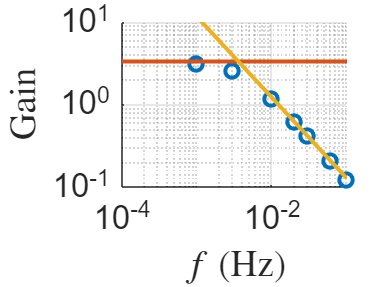

% Plot Bode diagram 
figure();
hold on;
grid on;
set(gca,'FontSize',25);
ylabel("$h_1$ (cm)",'Interpreter','latex');
xlabel('$t$ (s)','Interpreter','latex');
xlabel("$f$ (Hz)",'Interpreter','latex');
ylabel("Gain");
scatter(f(2:end),G(2:end),100,'LineWidth',3);
set(gca,'XScale','log','YScale','log')
plot([1e-4 max(f)], [G(1) G(1)],'LineWidth',3);
plot([1e-3 max(f)], [(10^reg(1))*(1e-3)^reg(2) (10^reg(1))*(max(f))^reg(2)],'LineWidth',3);
xlim([1e-4 max(f)])
ylim([1e-1 1e1]);
hold off;

## Pole - numeric simulation

% Estimate pole frequency by the frequency at which the linear regression
% of the asymptotic decrease equals the DC gain
p = 2*pi*10^((log10(G(1))-reg(1))/reg(2)) %rad/s

p = 0.0224

% Pole of the linearized system
p_th = cte.a(1)*sqrt(cte.g/(2*Ao_bar(1)))/cte.A(1) %rad/s

p_th = 0.0248

% Numerically determined DC gain
G0 = G(1)

G0 = 3.3200

% DC gain of the linearized system
G0_th = cte.gamma(1)*cte.k(1)*sqrt(2*Ao_bar(1)/cte.g)/cte.a(1)

G0_th = 3.2137

## Input data - experimental

% Experimental simulation
% quadruple_example_frequency_response_A = 8.00;
% Frequency (Hz)
f = [       0;      1e-3;   3e-3;   1e-2;   2e-2;   3e-2;   6e-2;   1e-1];
% DC component of output sinusoid (cm)
Ao_bar=[    12.32;  12.31;  12.05;  11.92;  11.77;  11.56;  11.55;  11.06];
% Amplitude input sinusoid (V)
Ai = [      0.5;    0.25;   0.5;    1.00;   2.00;   2.00;   4.00;   5.00];
% Amplitude output sinusoid (cm)
Ao = [      1.33;   0.6485; 1.364;  1.302;  1.307;  0.9185; 0.9528; 0.5525];

## Plot bode - experimental

% Compute gain
G = Ao./Ai;
% Select from which asymptotic gain decrease has been reached
idx_start = 4;
% Linear regression of the asymptotic gain decrease
reg = [ones(size(f(idx_start:end),1),1) log10(f(idx_start:end))]\log10(G(idx_start:end));
% Slope of asymptotic decrease in dB
dB_dec = 20*reg(2)

dB_dec = -20.8173

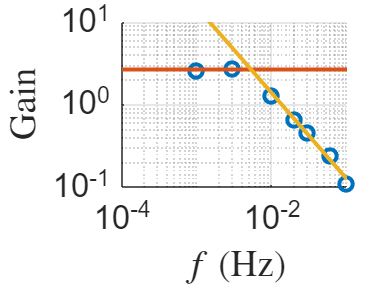

% Plot Bode diagram 
figure();
hold on;
grid on;
set(gca,'FontSize',25);
ylabel("$h_1$ (cm)",'Interpreter','latex');
xlabel('$t$ (s)','Interpreter','latex');
xlabel("$f$ (Hz)",'Interpreter','latex');
ylabel("Gain");
scatter(f(2:end),G(2:end),100,'LineWidth',3);
set(gca,'XScale','log','YScale','log')
plot([1e-4 max(f)], [G(1) G(1)],'LineWidth',3);
plot([1e-3 max(f)], [(10^reg(1))*(1e-3)^reg(2) (10^reg(1))*(max(f))^reg(2)],'LineWidth',3);
xlim([1e-4 max(f)])
ylim([1e-1 1e1]);
hold off;

## Pole - experimental

% Estimate pole frequency by the frequency at which the linear regression
% of the asymptotic decrease equals the DC gain
p = 2*pi*10^((log10(G(1))-reg(1))/reg(2)) %rad/s

p = 0.0331

% Pole of the linearized system
p_th = cte.a(1)*sqrt(cte.g/(2*Ao_bar(1)))/cte.A(1) %rad/s

p_th = 0.0263

% Numerically determined DC gain
G0 = G(1)

G0 = 2.6600

% DC gain of the linearized system
G0_th = cte.gamma(1)*cte.k(1)*sqrt(2*Ao_bar(1)/cte.g)/cte.a(1)

G0_th = 3.0310